# Hands-On: the Sample Average

## Introduction

In this MATLAB live script, we briefly introduce the sample average and median for readers less familiar with statistics. We highlight those aspects that will be important to interpret the results from the system identification point of view. We also use the opportunity to introduce estimators, a fundamental concept in system identification (please, refer to the L7 part of the class material for an introduction to  the propertiies and definitions regarding both the estimation and the prediction problem).

What you will learn:

- Sample mean $\hat \mu$ and sample median $\hat m$, 

- Study of the stochastic properties of $\hat \mu$ and $\hat m$,

- A system identification interpretation: Least Squares and Least Absolute Values,

- Discussion of the optimality of $\hat \mu$ and $\hat m$ as an estimator for the mean $\mu$ of a distribution.

## The Sample Mean

The expected value $E[X]$ of a random variable $X$ with distribution $F(X)$ is 


$$\text{E}[X] = \int_{-\infty}^{\infty}X\, d\, F(X)=\int_{-\infty}^{\infty}X\, f(X)dX$$


where the latter equality holds if the pdf (the probability density function) $f(X)$ exist.  The expected value is also known as the mean, average, or first moment. 

The **sample mean** of $N$ observations $\{x_i\}, i=1,\ldots,N$ of the random variable $X$ is defined as 


$$ {\bar {x}}={\frac {1}{N}}\sum _{i=1}^{N}x_{i}.$$


### The Sample Mean as an Estimator of the Mean Value of a Distribution

Consider the random variable $X\sim F(X)$with mean value $\mu = \text{E}[X].$ Then the sample mean $\bar x$ of $N$ observations  $\{x_i\}, i=1,\ldots,N$ of $X$ is an estimator $\hat \mu$ of the mean value $\mu$. The $\hat$ indicates that it is an estimated value.

*An ****estimator*** $\hat \theta$ is a function that calculates an estimate for a parameter $\theta$ that characterizes the observed variables, starting from the observations $\{x_i\}, i=1,\ldots,N$. In this case $\theta=\mu$, and the estimator  $\hat{\theta}=\hat{\mu}=\bar x$. 

The ***estimator*** $\hat \theta$ ***is a random variable***:  As the observations $x_i$ are samples of the random variable $X$, the estimate $\hat \theta$ that is a function of these samples $x_i$ is a sample of a random variable too.  We will use statistical tools to characterize $\hat \theta$. Below we discuss in more detail some aspects (expected value, variance, distribution) of the random behavior of $\hat \theta$.

*Multiple choices* for the estimator function are possible.  The system identification theory offers a systematic framework to understand better how to select the estimator that is best suited to solve a given problem, and to understand/study its stochastic properties. Here we will illustrate some aspects on the example of estimating the mean value of a distribution.

***An estimator is not unique***. For example, an alternative estimator for the mean value is

 
$$$\hat \mu_w= \displaystyle {\frac {\sum _{i=1}^{N}w_ix_{i}}{\sum _{i=1}^{N}w_i}}$ $$


 where $w_i$ is a user definable weighting. The  original estimator $\hat{\mu}=\bar x$ is retrieved by putting $w_i=1$. Please, have a look on the L7 class material and the related live scripts, where the choice of $w_i$ and its impact on the properties of $\hat \mu_w$ will be discussed. Later in this live scriipt, we study the median that can also be used as an alternative estimator for the mean of a symmetric distribution.

clear
close all
clc

### Study of the stochastic properties of the sample mean

#### Mean and Variance

In the example below, we illustrate the use of the estimator $\hat \mu = \bar x$ for the mean value $\mu$:


$$ \hat \mu_N=\bar {x}={\frac {1}{N}}\sum _{i=1}^{N}x_{i}.$$


 We  study its behavior for a growing number of samples (observations) $\{x_i\},i=1,\ldots,N$ drawn from a normal distribution $N(\mu=0,\sigma^2=1)$. In the figure we plot:

- $ \hat \mu_N$ for a growing number of samples $N$, using a logarithmic x-axis.

- On the left side, the results for a single realization of the simulation are shown. The points are connected by a line to give a better visual impression. 

- On the right plot, 10 realizations of the simulation are plotted on top of each other. These illustrate very well the **stochastic nature of **$ \hat \mu_N$, each realization results in a different line. However, some common characteristics can be observed.

- **Observations**: 1) The initial variations of $\hat \mu_N$ for small values of $N$ are large, but these drop to zero for growing values of $N$. 2) The $2\sigma_\mu$ error bound, plotted in red, decays to zero (see also next point). 3) All the blue lines converge to the true value $\mu=0$ for $N \rightarrow \infty$. The expected value $E[\hat \mu_N]=0$. 

- Exercise 1: prove that $E[\hat \mu_N]=0$ (Solution).

- *Error bounds*: In the plot the interval $[-2\sigma_\mu,2\sigma_\mu]$ is plotted in red around the true value $\mu=0$. The estimated value $\hat \mu_N$ is in this interval with a probability of about  95%.  This can be checked on the right plane of the plot. This information will be used in the next section on the Confidence interval to calculate confidence intervals on $\hat \mu_N$. 

- Exercise 2: show that for uncorrelated samples the variance $\sigma_\mu^2=E[(\hat \mu_N-\mu)^2]=\sigma^2/N$(Solution).

- Push the Run Again button to get another realization of the simulation.

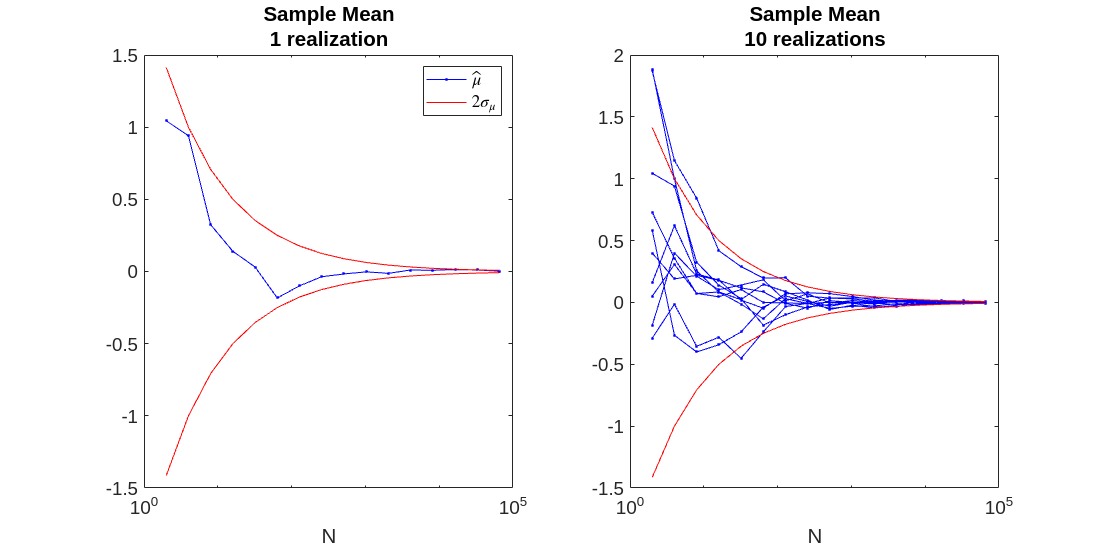

NAll=2.^(1:16); % let's create a few data sets: each dataset contains 2ˆN data
R = 10;         % how many repetitions?

 

% ---------------------
X = randn(max(NAll),R); % generate the random data as Gaussian r.v. with
                      % 0 as the mean value, and 1 as the variance value
% ---------------------

XmeanAll = zeros(numel(NAll), R); % preallocate memory in the workspace
                                  % filling the array with zeros
                                
% ---  calculate the mean values ---                                
for k = numel(NAll):-1:1     
    XmeanAll(k,:) = mean(X(1:NAll(k),:),1); 
end
% ---  calculate the mean values ---    


figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.75])
% --- Let's show what a single realisation looks like ---
hax1 = subplot(1,2,1);
semilogx(NAll,XmeanAll(:,1),'.-b',NAll,2./NAll.^0.5,'r',NAll,-2./NAll.^0.5,'r')
xlabel('N')
title({'Sample Mean','1 realization'})
legend({'$\hat{\mu}$','$2\sigma_\mu$'},'Interpreter','latex')
set(hax1, 'Fontsize', 14)
% --- Let's show the 10 realizations ---
hax2 = subplot(1,2,2);
semilogx(NAll,XmeanAll(:,1:10),'.-b',NAll,2./NAll.^0.5,'r',NAll,-2./NAll.^0.5,'r')
xlabel('N')
title({'Sample Mean','10 realizations'})
set(hax2, 'Fontsize', 14)

#### Confidence interval

The confidence interval gives an idea about the reliability of a result with respect to random variations, it does not include the impact of systematic errors (bias errors). These should be studied through a theoretical analysis, or eliminated by making a calibration measurement.  Since $E[\hat \mu_N]=\mu$ (see Exercise 1), we have that the bias of the sample mean is zero so that we can focus completely on the random variations.

The $1-\alpha$ uncertainty interval of $\hat \mu_N$ is the interval $[\hat \mu_N- a\sigma , \hat \mu_N + a\sigma ] $ with the value $a$ selected such that

 $P (\mu \in  [\hat \mu_N- a\sigma , \hat \mu_N + a\sigma ]) = 1 - \alpha $. 

Here, α is the probability that the true value $\mu$ lays outside the considered interval. The width of the interval is set by the choice of $a$ and the desired value of $\alpha$. For example, for a normal distribution and $a=1.96$, we have  that $\alpha=0.05$, resulting in the 95% uncertainty interval. Observe that the relation between $a$ and $\alpha$ depends on the distribution of $\hat \mu_N$. This distribution will be studied in the next section. Other commonly used values of $a$ are $a=1, P=68.27\%$, $a=2$, $P=95.45 \%$, and $a=3, P=99.73\%$.

The confidence interval is centered around $\hat \mu_N$ that varies from one realization to the other, so also the uncertainty interval will vary. However, by definition we know that there is a probability of $1-\alpha$ that the true value $\mu$ is in the interval.

Remarks

- In practice, the value $\sigma$ is unknown and has to be estimated as well. This will be discussed in the Hands-On [*The* *Sample Variance*](matlab:open('./L6_HandsON_SampleVariance.mlx'))*.*

- The distribution of the estimate $\hat \mu_N$ strongly influences the choice of $a$, especially from small values of $N$, for example $N\leq10$. In the next section it will be shown that for a growing value of $N$ the distribution of  $\hat \mu_N$ becomes asymptotically normal, so that in practice the table of the normal distribution can be used in most cases.

In the next figure, the sample mean of $\{x_i\},i=1,\ldots,N$ drawn from a normal distribution $N(\mu=0,\sigma^2=1)$is shown for $R$ realizations.

- Vary the width $a$ of the interval. Check for $a=1,2,3$ how many of the realizations include the true value $\mu=0$ in the interval. Repeat the experiment by pushing the button Run Again. 

- Vary the number of samples $N$. Does this change the previous results?

- Exercise 3: How does the width of the confidence interval vary with $N$? What should be the value of $N$ to get a 95% uncertainty interval with a width of 0.4?

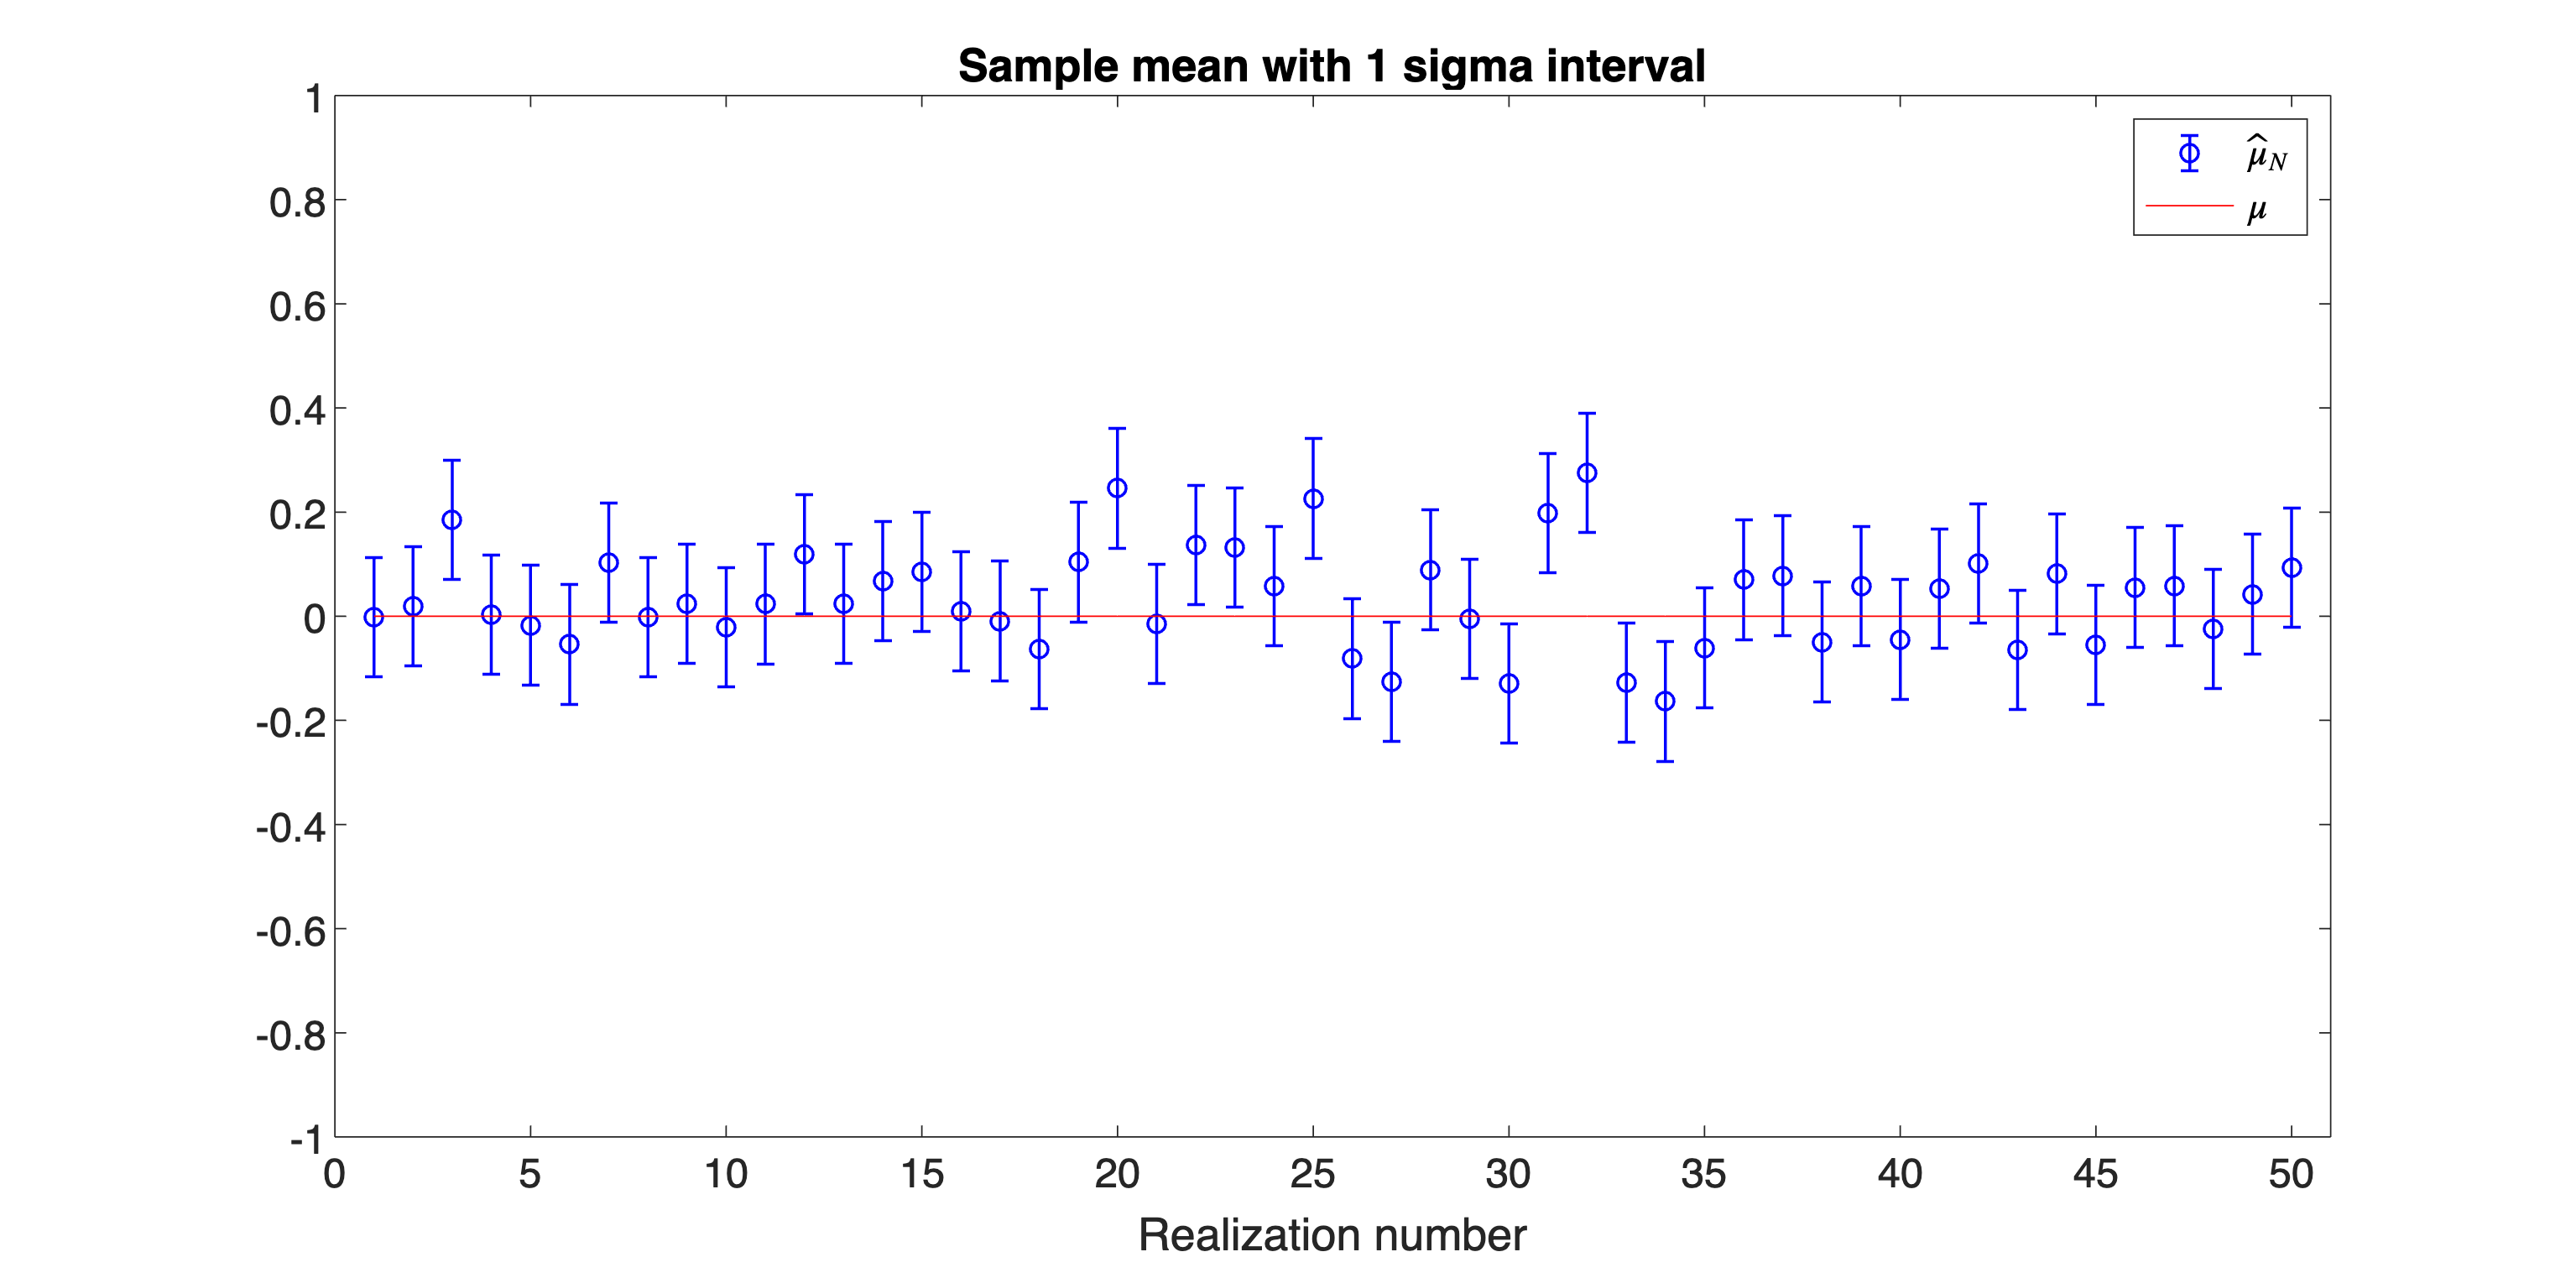


N =76;  % number of samples
R =50;  % number of realization
a =1;    % number of standard deviations

 

X = randn(N,R); % let's generate the r.values

XmeanAll = mean(X,1); % the running mean


figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.75])

sigmaMean=1/sqrt(N);     % the std. dev. the estimated mean value
errorbar(XmeanAll,a*sigmaMean*ones(size(XmeanAll)),'ob','linewidth',1)
hold on
plot((1:R),zeros(1,R),'r')
hold off
axis([0 R+1 -1 1])
legend('$\hat\mu_N$','$\mu$','Interpreter','latex')
xlabel('Realization number')
title(['Sample mean with ',num2str(a),' sigma interval'])
set(gca, 'Fontsize', 14);

#### Distribution of the sample mean: a first impression (Hint: Not for One New to Statistics)

The sample mean $\hat \mu$ of a random variable $X$ is a random variable as well. It has a distribution $F_{\hat\mu}$ and pdf  $f_{\hat\mu}$ (assuming that the derivative of $F_{\hat\mu}$ exists) that depend on the original distribution $F_X$ of $X$. In the next illustration, we show that $F_{\hat\mu}$, $f_{\hat\mu}$ converge to a normal distribution for $N \rightarrow \infty$, independently of the original distribution $F_X$. This follows directly from the **central limit theorem** that applies to all distributions with a finite variance. 

We start from two different distributions $F_X$: a normal distribution, and a uniform distribution. All have a zero mean ($\mu=0$) and a unit variance ($\sigma^2=1$).  For the three situations, $\hat \mu_N$ is calculated for $N=2,4,16$ and this for $R=10^4$ realizations. For the normal and uniform distribution, the estimated pdf of $\hat \mu_N$ is plotted. For the binary distribution the probability mass function (pmf) is shown, the pdf does not exist in this case (why?). From this plot the following observations can be made:

-  *Normal distribution *$X\sim N(0,1)$: $\hat \mu \sim N(0,1/N)$. The normal distribution for $\hat\mu$ follows from the property that a linear combination of normally distributed random variables is also normally distributed. The mean value and variance are calculated in Exercises 1 and 2.

- *Uniform distribution* $X\sim U_{[-\sqrt{3},\sqrt{3}]$: Replacing the normal distribtuion $X\sim N(0,1)$ by  the uniform distribution $X\sim U_{[-\sqrt{3},\sqrt{3}]$  (check that $X$ has a zero mean and a unit variance) does not change the mean and variance of $\hat \mu$ (see the solutions of  Exercises 1 and 2): $E[\hat \mu]=0$ and $\sigma_\mu^2=E[(\hat \mu_N-\mu)^2]=\sigma^2/N$, but the distribution changes. 1) $N=2: $The pdf $f_Y$of the sum of two random variables $Y=X_1+X_2$ is given by the convolution $f_Y=F_{X_1} \ast F_{X_2}.$ The convolution of two rectangular functions is a triangular with double width. 2) $N=4$: This can be considered as $Y=(X_1+X_2)+(X_3+X_4)$, where the two terms in the sum have both a triangular distribution. The convolution of the two triangular functions starts to look like a normal distribution. The similarity is even better for $N=16$.

- Repeat the simulation a few times and observe the (small) random fluctuations in the estimated results. For lower values of $R$, these variations would become larger.

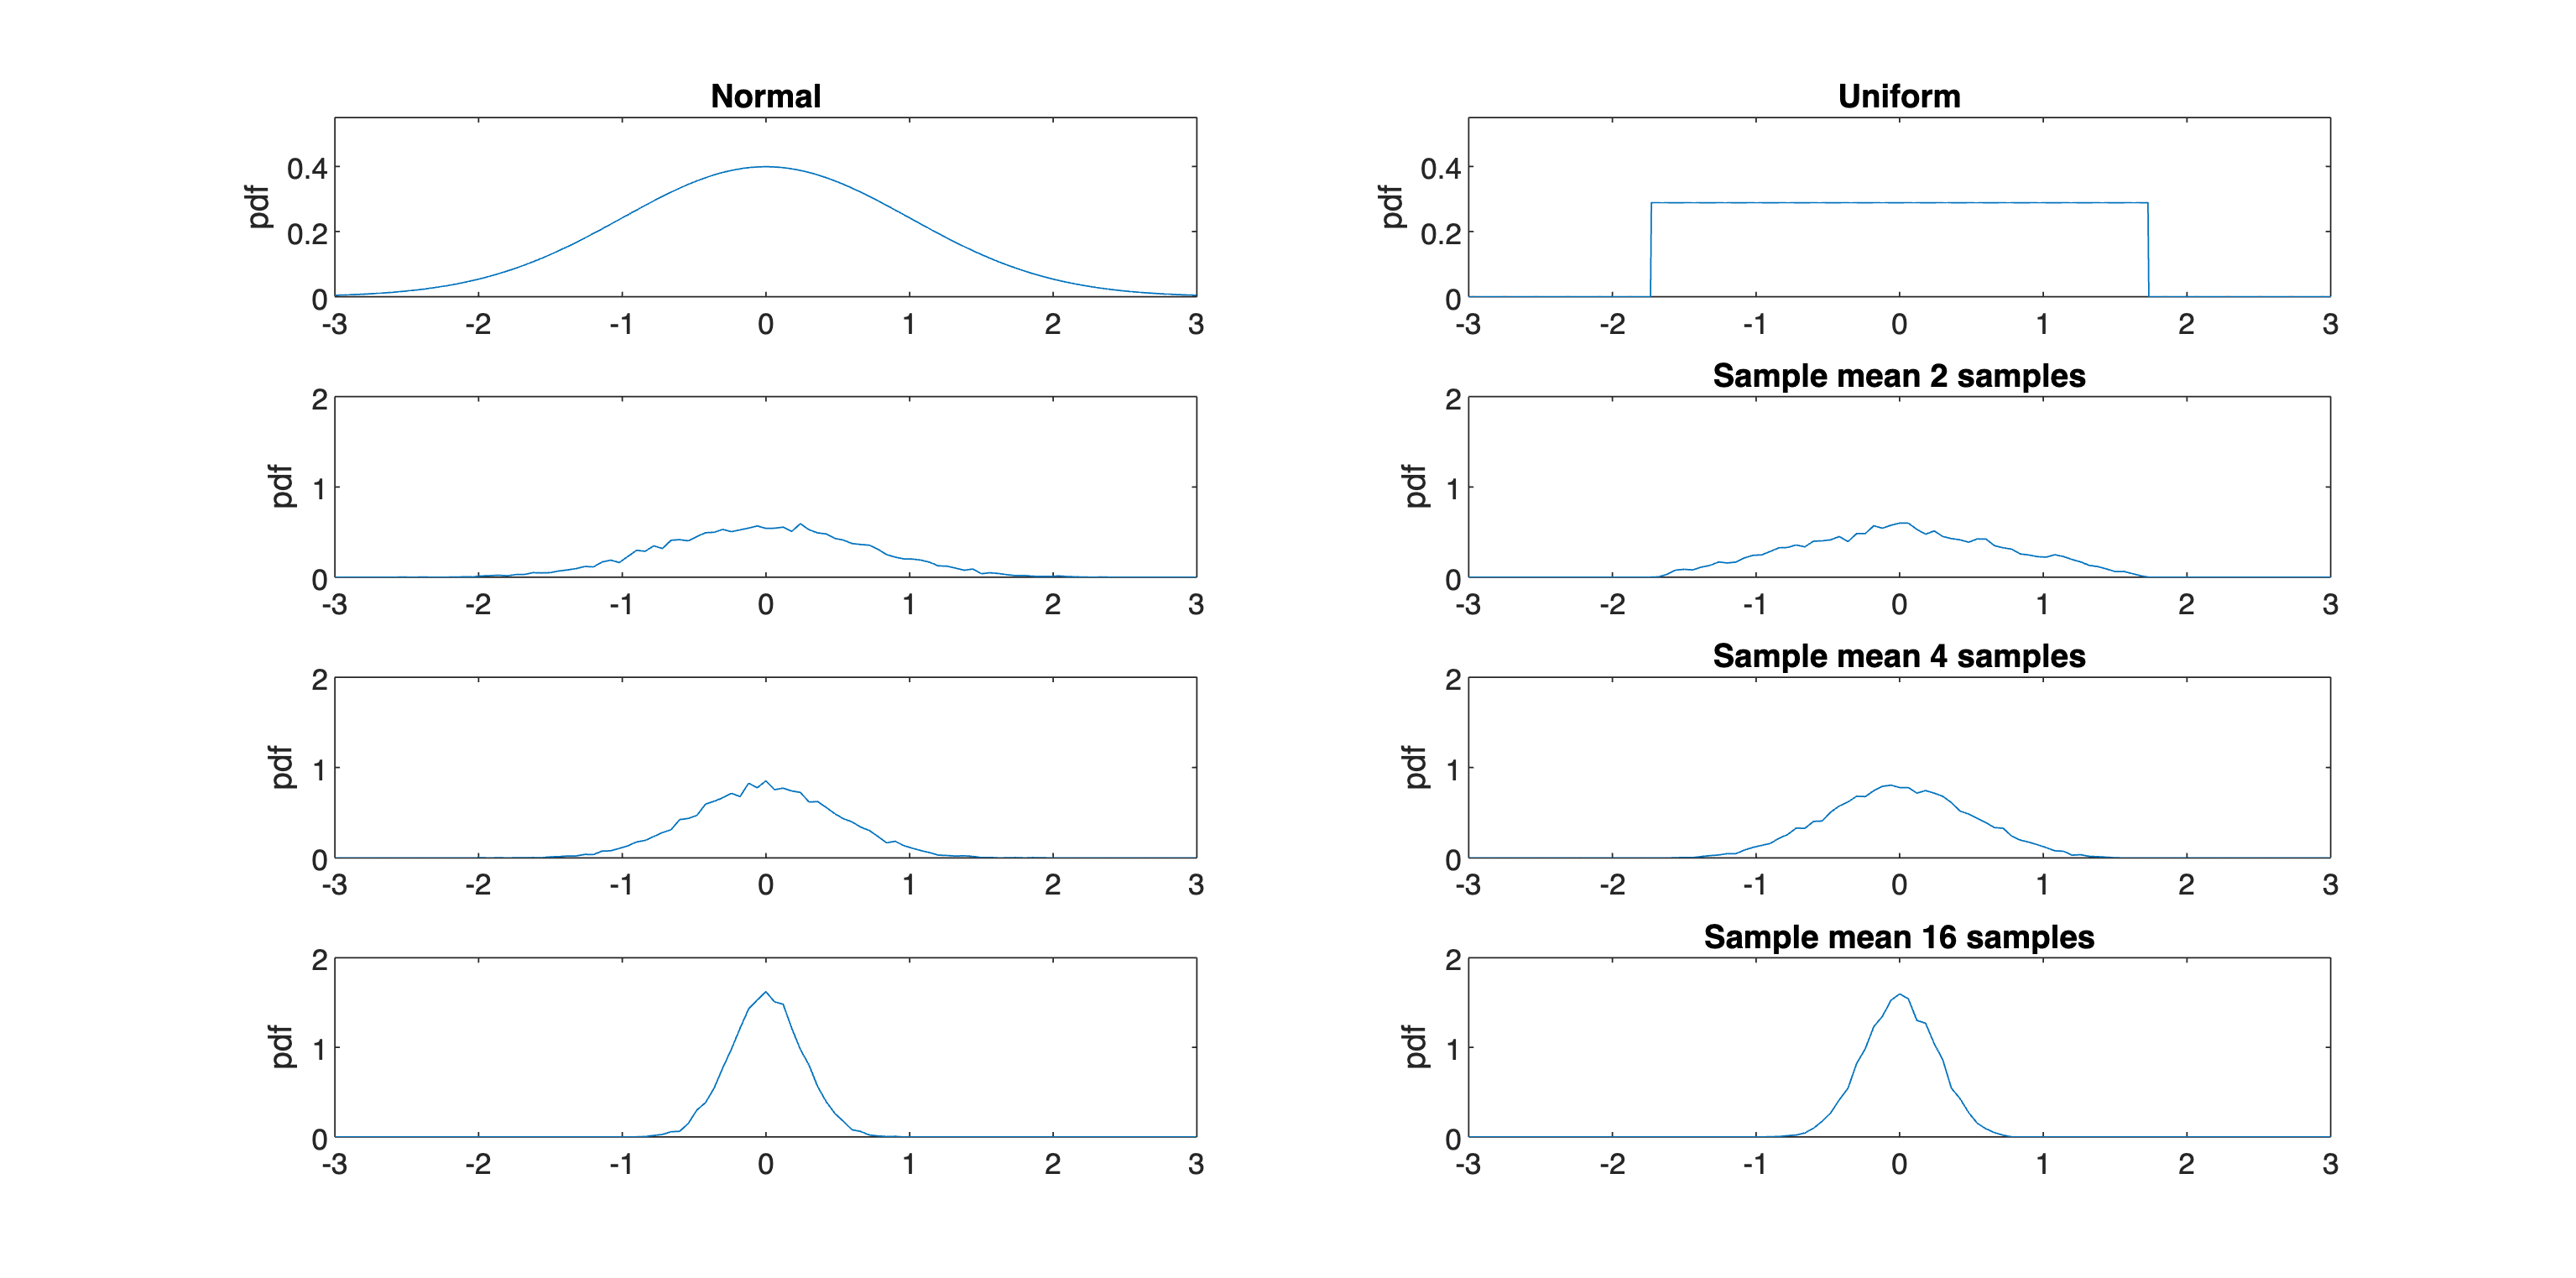


% ------ distribution sample mean ------
NAll=[2 4 16];nAll=length(NAll);
R=10000;

 

% --- plot starting distributions ---
c=linspace(-3,3,1001);  % centers for the pdf calculations

XNorm0pdf=normpdf(c);  % normal distribution

XUnif0pdf=zeros(size(c));XUnif0pdf(abs(c)<=sqrt(3))=0.5/sqrt(3); % Uniform distribution


Center=linspace(-3,3,101);d=Center(2)-Center(1);  % centers for the histogram

XNorm = randn(max(NAll),R);
XUnif = (rand(max(NAll),R)-0.5)*sqrt(12);  % generate uniform distribution with unit variance

for k=length(NAll):-1:1
    XmeanAllNorm(k,:)=mean(XNorm(1:NAll(k),:),1);
    XmeanAllUnif(k,:)=mean(XUnif(1:NAll(k),:),1);
end

figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.75])

% theoretical distributions
subplot(nAll+1,2,1), 
plot(c,XNorm0pdf),title('Normal'),axis([-3,3,0,0.55]),ylabel('pdf')
subplot(nAll+1,2,2), 
plot(c,XUnif0pdf),axis([-3,3,0,0.55]),title('Uniform'),ylabel('pdf')


% sample distributions of the sample mean
for k=1:nAll
    [n]=hist(XmeanAllNorm(k,:),Center);pdfEst=n/R/d;
    subplot(nAll+1,2,2*k+1);
    plot(Center,pdfEst),axis([-3,3,0,2]);
    ylabel('pdf')

    [n]=hist(XmeanAllUnif(k,:),Center);pdfEst=n/R/d;
    subplot(nAll+1,2,2*k+2);
    plot(Center,pdfEst)
    axis([-3,3,0,2]);
    title(['Sample mean ',num2str(NAll(k)),' samples']);
    ylabel('pdf')
end

## Sample median - Sample mean (Non e` argomento del corso)

###  Definition of the median

The median $m$ of $X\sim F_X$ is defined as $P (X\leq m)\geq \frac {1}{2}$ and $P (X\geq m)\geq \frac {1}{2}$, it is the value that splits the probability mass in two equal parts. 

For example, the median of $X=\{1,3,3,3,7\}$ is $m=3$. Observe that in this case $P(X\leq 3)=4/5$ and $P(X\geq 3)=4/5$ which is in agreement with the definition. For a discrete set with an odd number of samples $N$, the median is $m =\tilde x_{(N+1)/2}$, with $\tilde X$ the samples arranged in increasing order such that $\tilde x_{k}\leq\tilde  x_{k+1}$. For a discrete set with an even number of samples $N$, the median is the interval $m \in[\tilde x_{N/2},\tilde x_{N/2+1}]$. In that case, the center value of the interval is often selected as the median $m =(\tilde x_{N/2}+\tilde x_{N/2+1})/2$.

### The sample median as an estimate for the mean

For a normal distribution $X\sim N(\mu,\sigma^2)$, the median is $m=\mu$.  This shows that the sample median $\hat m=median(\{x_i\},i=1,\ldots,N)$ with $x_i$ drawn from the normal distribution is also an estimate for its mean value $\mu$.  

This is true for all symmetric distributions. For a symmetric distribution, the probability mass is symmetrically distributed around its mean value (for example $f_X(\mu-\delta)=f_X(\mu+\delta)$)   and hence the median equals the mean $m=\mu$.

### The sample mean and sample median of a normal distribution

This raises the question which is the best estimator for  the mean value $\mu$ of a random variable $X\sim F_X$. Is it the sample mean $\hat \mu$ or the sample median $\hat m$? In the next figure, the result of a simulation for $X\sim N(\mu=0,\sigma^2=1)$ is shown.

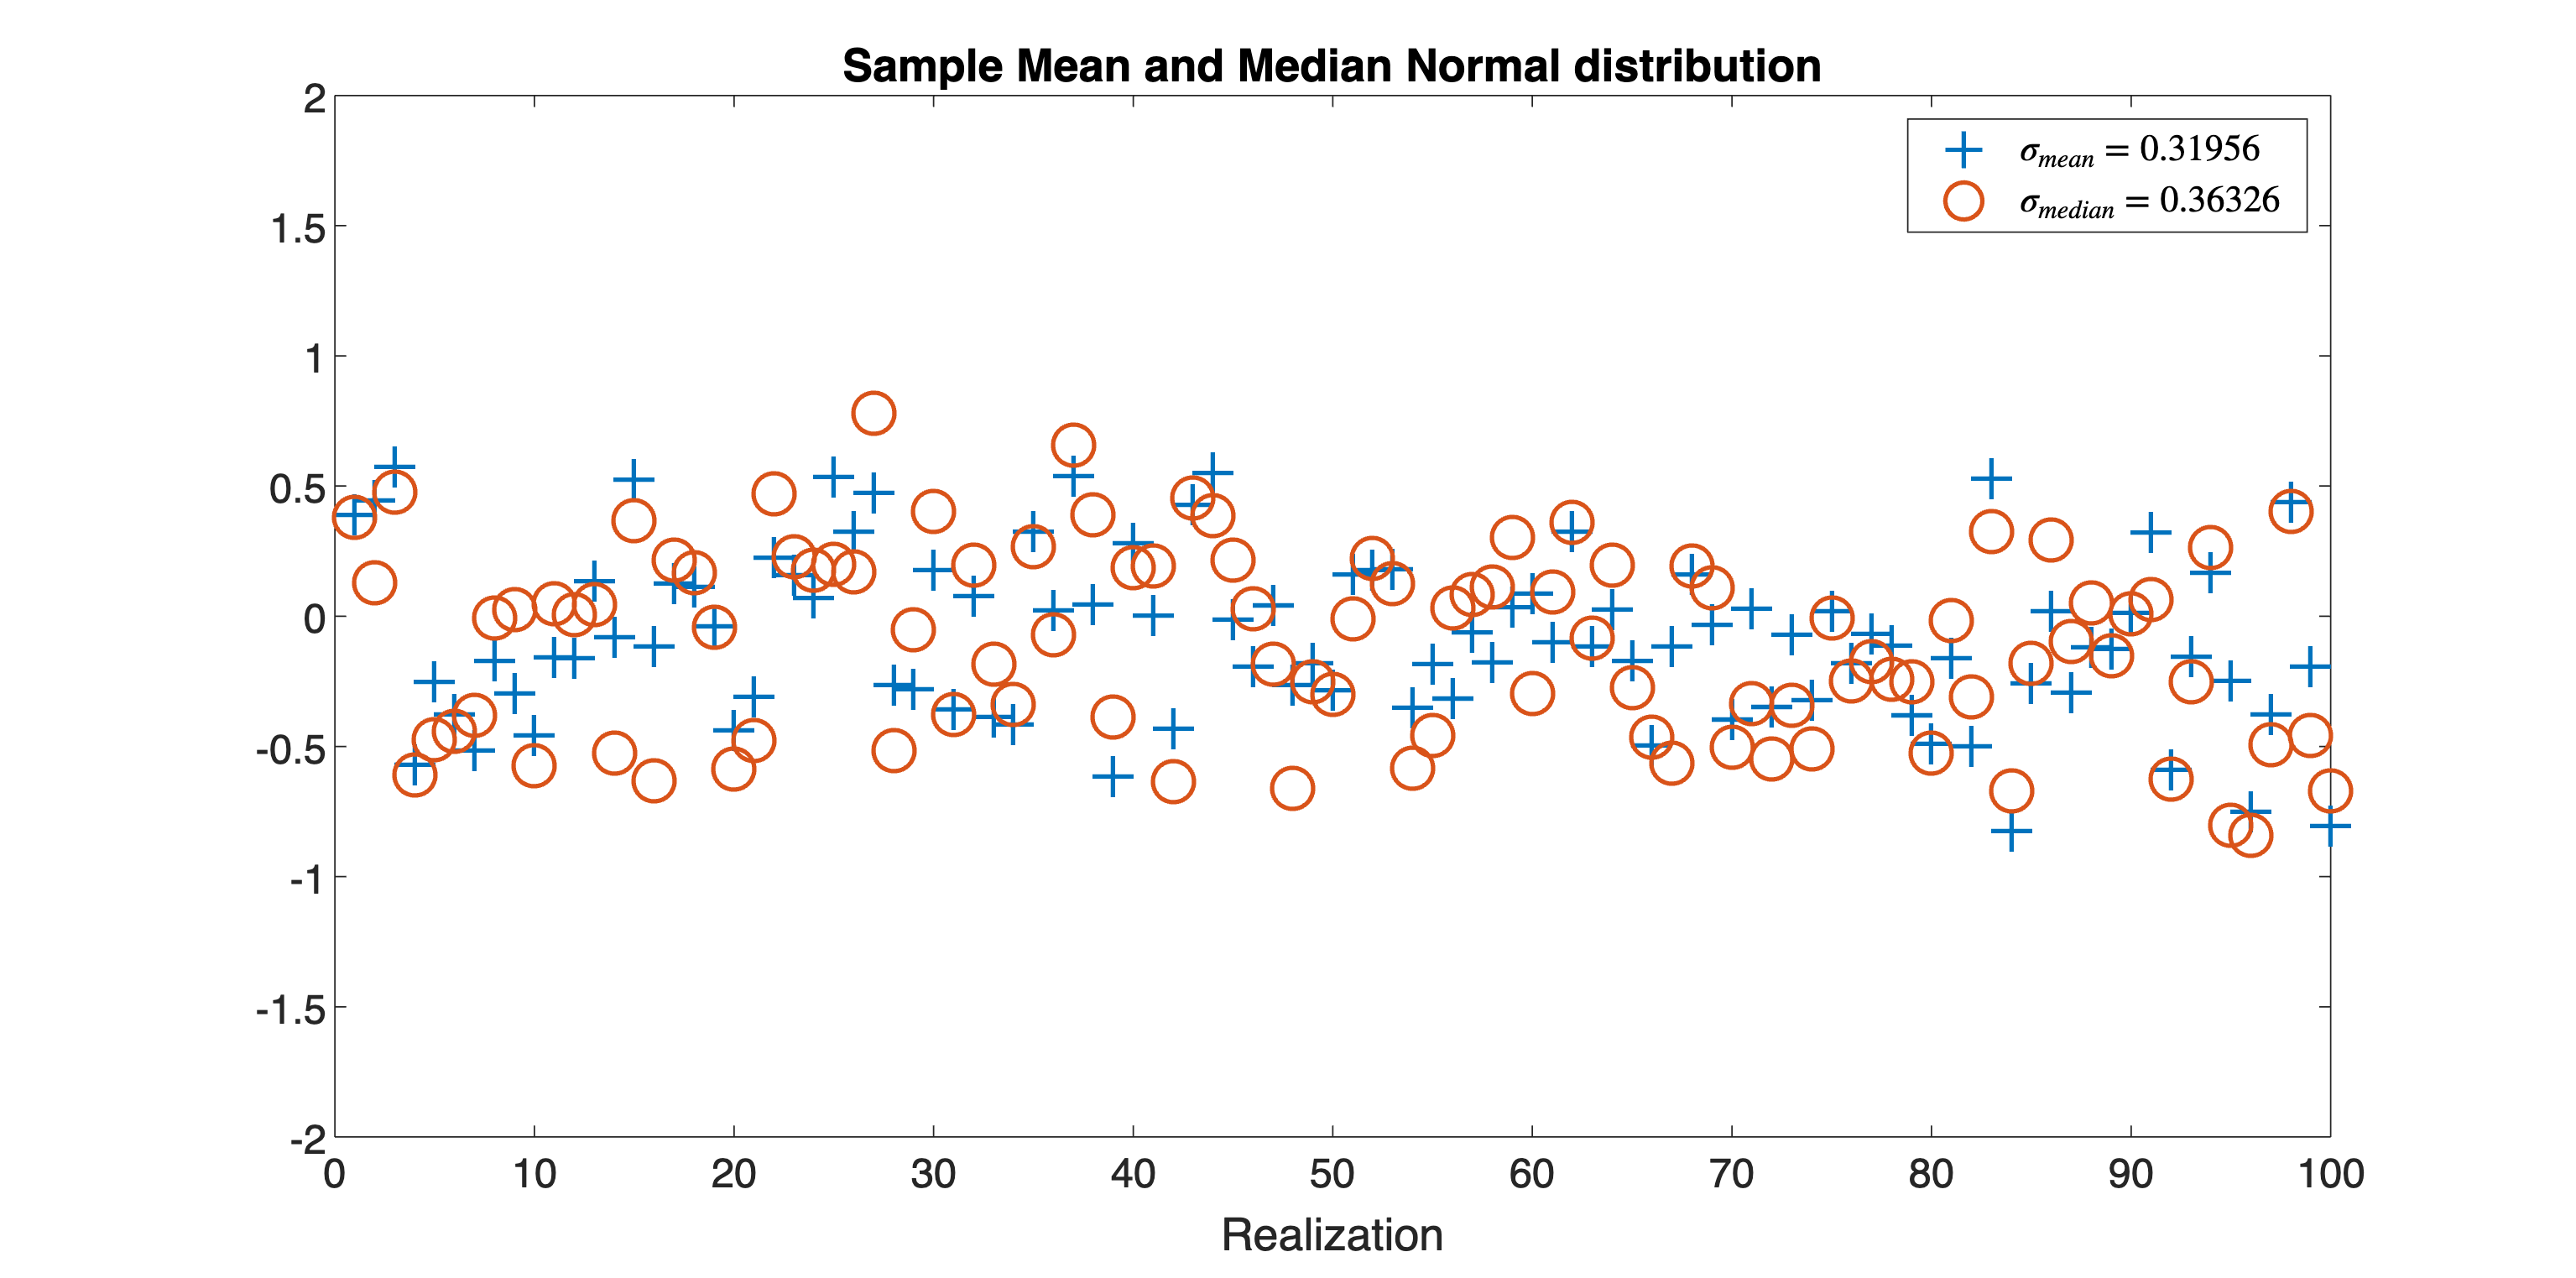

N=10;
R=100;
 

X=randn(N,R);   % generate R realizations of length N
Xmean = mean(X,1);
Xmedian = median(X,1);

figure('Units','normalized','Position',[0.1, 0.1, 0.85, 0.75])

plot(1:R,Xmean,'+',1:R,Xmedian,'o', 'MarkerSize', 14, 'LineWidth', 1.5)
title('Sample Mean and Median Normal distribution')
xlabel('Realization')
axis([0 R -2 2])
legend(['$\sigma_{mean} = $',num2str(std(Xmean))],...
['$\sigma_{median} = $',num2str(std(Xmedian))],'interpreter','latex')
set(gca, 'Fontsize', 14)

This suggests that $\hat\mu$ has a smaller standard deviation than $\hat m$ and hence is to be preferred. However, the full answer depends on the nature of the distribution $F_X$. 

## What You Learned

We introduced the sample mean and studied its use as an estimator for the mean value of a random variable. We put the results also in a system identification setting.

The sample mean $\hat \mu=\bar x$ calculated from a finite number of samples is also a random variable. 

The sample mean is an unbiased estimate of the mean $\mu$. Its expected value equals the true value $E[\hat \mu]=\mu$, or, in system identification terms, $E[\hat \theta]=\theta_0$.

The standard deviation $\sigma_{\hat \mu}=\sigma_e/\sqrt{N}$, it drops to zero for a growing number of samples. If the number of samples is multiplied with 100, the standard deviation is reduced with a factor 10. This is a rather slow reduction, the cost to make longer experiments can grow fast.

The sample mean $\hat \mu$ is asymptotically normally distributed, independent of the distribution of the 'disturbing' noise $e$. The convergence for the tails of the distribution is slower than that of the 'bulk' of the distribution.

This information can be used to construct a confidence interval around $\hat \mu$ that contains $\mu$ with a user defined probability.

The median $\hat m$ is an alternative estimator to estimate the mean of a symmetric distribution. This shows that an estimator is not unique, multiple possibilities exist. 

The median is less sensitive to outliers, but for the normal distribution it has a larger uncertainty than the sample mean. 

## Solutions

### Expected value of the sample mean

The expected value of the sample mean is easy to calculate using the linearity property of the expected value: $E[X+Y]=E[X]+E[Y]$. Applying this to $\hat\mu_N= \frac{1}{N}\sum_{i=1}^Ny_i$ results in

$E[\hat\mu_N]= E[\frac{1}{N}\sum_{i=1}^Ny_i]=\frac{1}{N}\sum_{i=1}^NE[y_i]=\frac{1}{N}\sum_{i=1}^N\mu=\mu$.

### Variance of the sample mean

The variance of the sample mean was obtained in the Least Squares Solution section: $\sigma_{\hat \mu_N}^2=\sigma_e^2/N$. Here we will calculate it directly from $\hat\mu_N= \frac{1}{N}\sum_{i=1}^Ny_i$. The experimental data  $\{y_i\}, i=1,\ldots,N$ are drawn from the distribution with mean value $\mu$: $F_Y(\mu)$. So, it follows that $E[e_i]=E[y_i-\mu]=\mu-\mu=0$, and 

$\hat\mu_N= \frac{1}{N}\sum_{i=1}^Ny_i=\mu+\frac{1}{N}\sum_{i=1}^Ne_i=\mu+v$, with $v=\frac{1}{N}\sum_{i=1}^Ne_i$.

So the problem is reduced to the calculation of the variance of $v$ that has a zero mean value.


$$\sigma_e^2=E[(\frac{1}{N}\sum_{i=1}^Ne_i)^2]=\frac{1}{N^2}E[\sum_{i=1}^N\sum_{j=1}^Ne_ie_j]$$


Observing that for uncorrelated noise $E[e_ie_j]=0$ if $i\neq j$, and that $E[e_ie_i]=E[e_i^2]=\sigma_e^2$, reduces the previous result to

$\sigma_e^2=\frac{1}{N^2}E[\sum_{i=1}^N\sigma_e^2]=\frac{1}{N^2}N\sigma_e^2=\sigma_e^2/N$.